# Motor Model & LTI Parameters 

% source: http://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling
%         https://aleksandarhaber.com/modeling-a-dc-motor-and-matlab-simulation/

clear all
close all
clc

% (J)     moment of inertia of the rotor     0.01 kg.m^2
% (b)     motor viscous friction constant    0.1 N.m.s
% (Ke)    electromotive force constant       0.01 V/rad/sec
% (Kt)    motor torque constant              0.01 N.m/Amp
% (R)     electric resistance                1 Ohm
% (L)     electric inductance                0.5 H

J = 0.01;
b = 0.1;
Ke = 0.01;
Kt = 0.01;
R = 1;
L = 0.5;

A = [-b/J Kt/J; -Ke/L -R/L];
B = [0; 1/L];
C = [1 0];

eig(A)

ans =    -9.9975
   -2.0025


rank(ctrb(A,B))

ans = 2


sys = ss(A,B,C,[]);
x0 = [0; 0];

# Timing Parameters

dt = 0.02;
t_total = 10;
t_attack = 5;
t_span = 0:dt:t_total;

% target measurement - pulse
ref_fuc = @(i) 5-mod(floor(i*dt/4),2);
ref = zeros(size(t_span,2),1);
for i = 1:length(ref)
    ref(i,1) = ref_fuc(i);
end

# PID Parameters

global windupGuard;
global proportional_gain;
global integral_gain;
global derivative_gain;
global prev_error;
global int_error;
global control;

% set these as needed
control = 0;
windupGuard = 100;
proportional_gain = 20;%19.43;
integral_gain = 40;%0.6142;
derivative_gain = 1;%0.08856;
 
% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

% call update function
%pid_update(19, 1.0)

# Simulation - No attacks

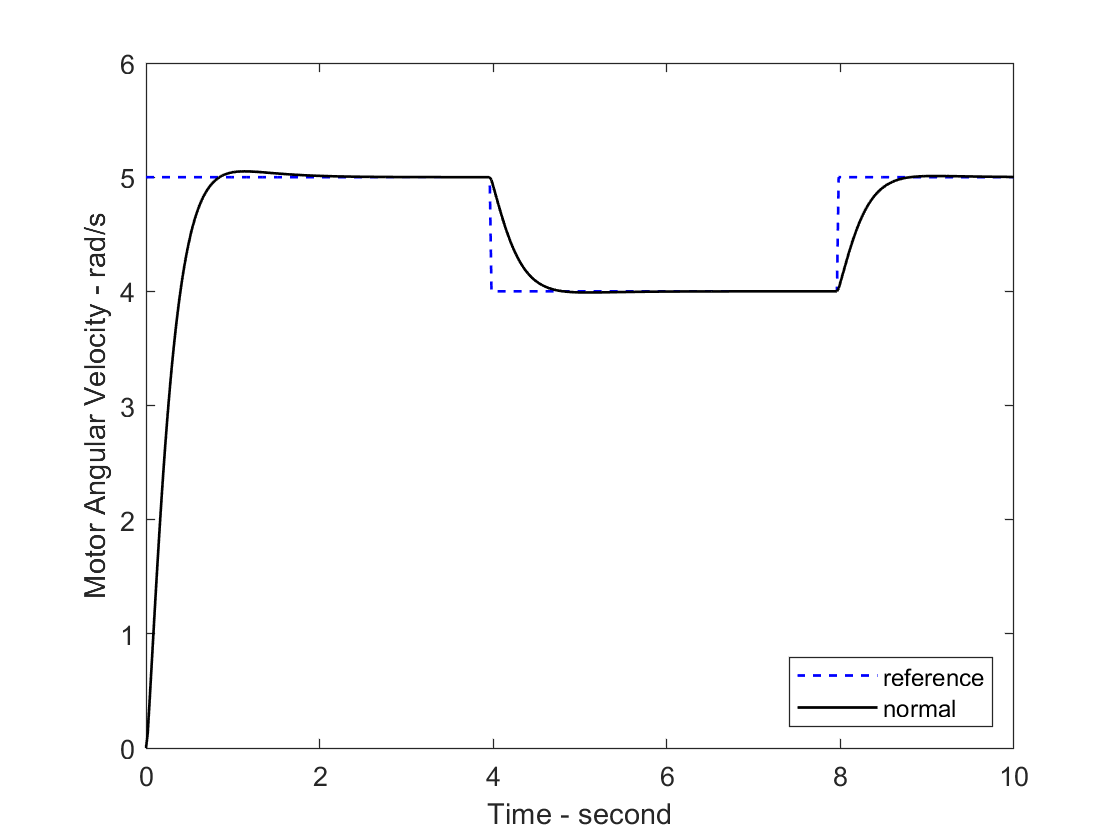

close all

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
y = C * x0;

for i = 2:(t_total/dt+1)
    error = ref(i,1) - y(end,1);
    pid_update(error, dt);
    [y,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end


plot(t_span,ref(:,1),'b--',t_span,x(:,1),'k', 'LineWidth', 1);
ylabel('Motor Angular Velocity - rad/s');
xlabel('Time - second');
legend('reference','normal','Location','SouthEast');

# Simulation - Attack, No recovery

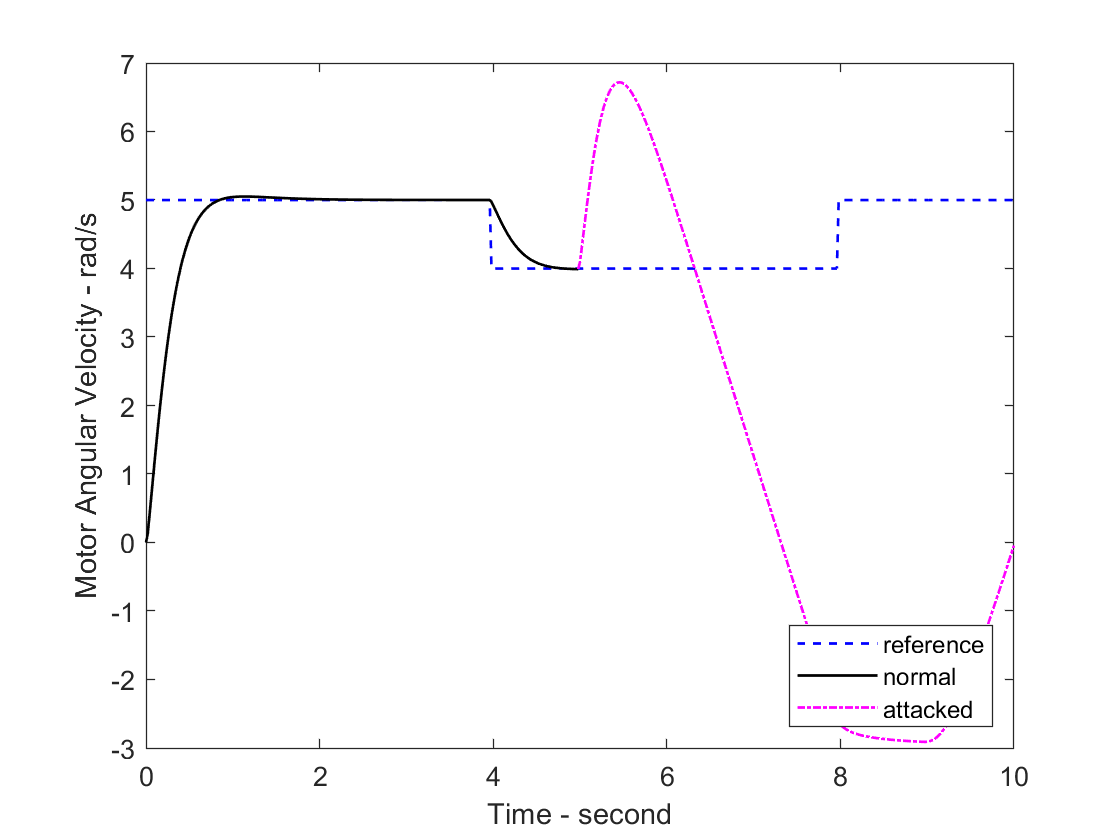

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1);  
y(1,:) = C * x0;
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = C * x0;


attack_type = "replay";

% flag
attacked = 0;
last_normal = 0;

for i = 2:(t_total/dt+1)
    if i > t_attack/dt
        if ~attacked
            last_normal = y(i-1,1);
            attacked = 1;
        end
        if strcmp(attack_type,'delay')
            y_dirty(i-1,1) = last_normal;
        elseif strcmp(attack_type,'alter')
            %y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
            y_dirty(i-1,1) = y(i-1,1) + 2;
        elseif strcmp(attack_type,'replay')
            y_dirty(i-1,1) = y(0+(i-t_attack/dt));
        end
    end
    
    error_dirty = ref(i,1) - y_dirty(i-1,1);
    pid_update(error_dirty, dt);
    
    [ytemp,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp(end,:);
    y_dirty(i,:) = ytemp(end,:);
    
end


pa = t_attack/dt;
plot(t_span,ref(:,1),'b--',t_span(1,1:pa),x(1:pa,1),'k', ...
    t_span(1,pa:end),x(pa:end,1),'m-.', 'LineWidth', 1);
ylabel('Motor Angular Velocity - rad/s');
xlabel('Time - second');
legend('reference','normal','attacked','Location','SouthEast');

# Simulation - Attack, With recovery

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1);  
y(1,:) = C * x0;
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = C * x0;


attack_type = "alter";

% flag
attacked = 0;
last_normal = 0;
detected = 0;
reset = 0;

for i = 2:(t_total/dt+1)
    % detection here
    if i > (t_attack+0.2)/dt
        detected = 1;
    end
    % end of detection 
        
    if i > t_attack/dt
        if detected
            % recovery here
            if ~reset
                reset = 1;
%                 % this is the zeroize function
%                 prev_error = 0.0;
%                 int_error = 0.0;                
                disp('recoverd!');
            end
            % end of recovery  
        else
            if ~attacked
                last_normal = y(i-1,1);
                attacked = 1;
            end
            if strcmp(attack_type,'delay')
                y_dirty(i-1,1) = last_normal;
            elseif strcmp(attack_type,'alter')
                %y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
                y_dirty(i-1,1) = y(i-1,1) + 2;
            elseif strcmp(attack_type,'replay')
                y_dirty(i-1,1) = y(0+(i-t_attack/dt));
            end
        end
    end
    
    error_dirty = ref(i,1) - y_dirty(i-1,1);
    pid_update(error_dirty, dt);
    
    [ytemp,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp(end,:);
    y_dirty(i,:) = ytemp(end,:);
    
end

recoverd!


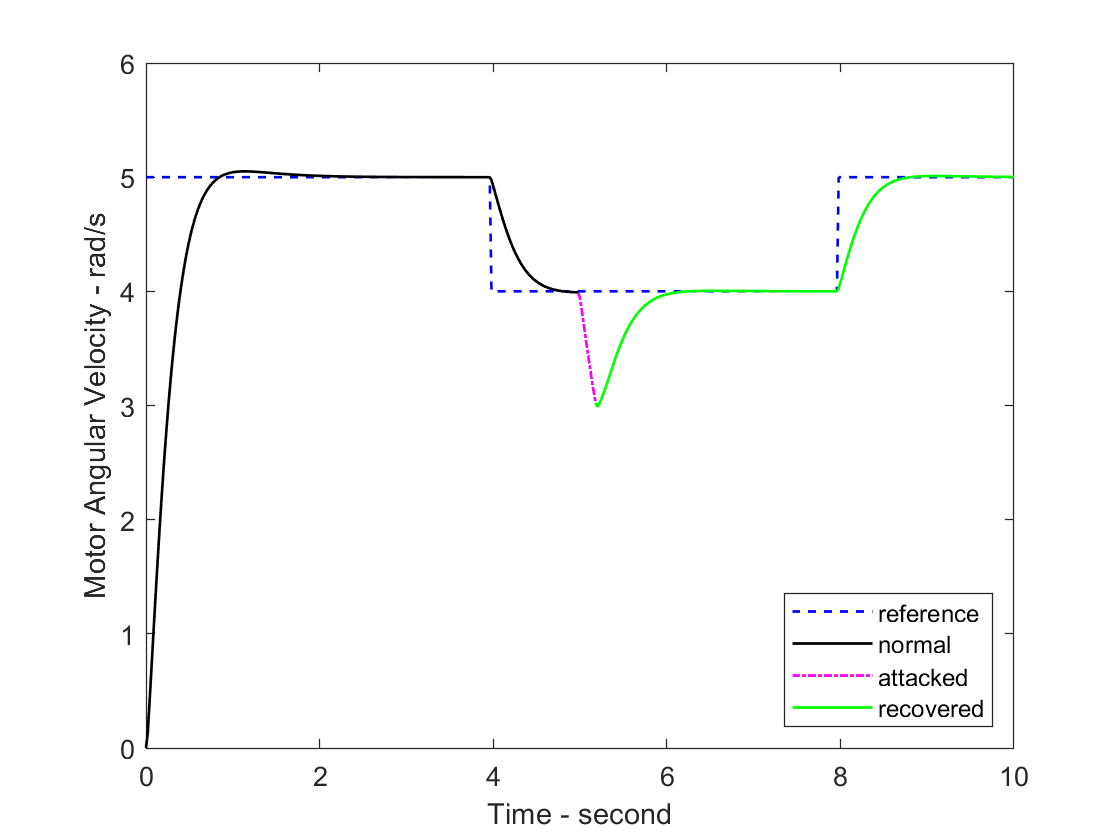


pa = t_attack/dt;
pr = (t_attack+0.2)/dt;
plot(t_span,ref(:,1),'b--', ...
    t_span(1,1:pa),x(1:pa,1),'k', ...
    t_span(1,pa:pr),x(pa:pr,1),'m-.', ...
    t_span(1,pr:end),x(pr:end,1),'g', 'LineWidth', 1);
ylabel('Motor Angular Velocity - rad/s');
xlabel('Time - second');
legend('reference','normal','attacked','recovered','Location','SouthEast');